Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 1 sec


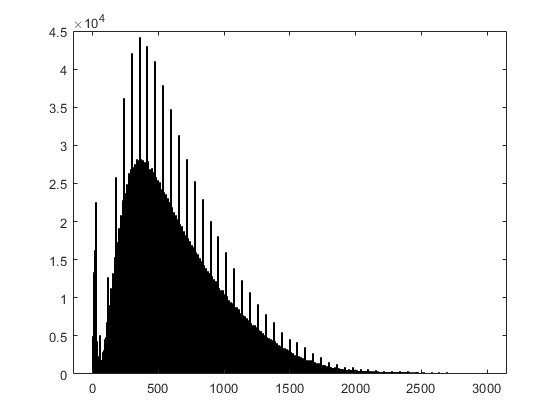

%Creation of histogram for Travel Time
    histogram(myOpenData_FullYear.Travel_Time_Seconds,400,'BinLimits',[1,3000]);

%Request for elevation details on certain locations
    %Elevation_PreHTTPRequest = table2array(stations);
    %Elevation_HTTP_Request

%Already calculated elevation for each station (Already performed and stored on DatabaseOfStationsRoutes)

%     load('stations_with_ElevationData.mat')
%     stations = array2table(Elevation_PreHTTPRequest,'VariableNames',{'id','latitude', 'longitude', 'elevation'});
%     Ar_stations = table2array(stations);
%     [num_stations,~] = size(Ar_stations);
%     StationsCombinationsNumber = nchoosek((Ar_stations(:,1))', 2);
%     myCombinations = array2table(StationsCombinationsNumber,'VariableNames',{'id','id_2'});
%     myCombinations = join(myCombinations,stations);
%     myCombinations.Properties.VariableNames{1} = 'id_origin';
%     myCombinations.Properties.VariableNames{2} = 'id';
%     myCombinations.Properties.VariableNames{3} = 'latitude_origin';
%     myCombinations.Properties.VariableNames{4} = 'longitude_origin';
%     myCombinations.Properties.VariableNames{5} = 'altitude_origin';
%     myCombinations = join(myCombinations,stations);
%     myCombinations.Properties.VariableNames{2} = 'id_dest';
%     myCombinations.Properties.VariableNames{6} = 'latitude_dest';
%     myCombinations.Properties.VariableNames{7} = 'longitude_dest';
%     myCombinations.Properties.VariableNames{8} = 'altitude_dest';

%Do not uncomment unless all combinations need to be recalculated using Google APIS (13 hours run-time)
%I had to remove my API key because every time this HTTP_Request runs, the cost is 140 USD for 30k Request.
%In case it has to be re-run please populate your own API key on the HTTP_Request.m file

    %PreHTTPRequest = table2array(myCombinations);
    %HTTP_Request

%Already calculated distances will be loaded instead of recalculated
%Do not keep previous two lines uncommented if the following lines are used.
    %load('table_AllCombinationsBetweenStations_GoogleData_Distance_Time.mat');
    %load('table_AllCombinationsBetweenStations_GoogleData_Distance_Time_Latitude.mat') %Already imported by DA_Analyze.mlx

%Definition of Local Constants
    MAX_NUMBER_STATIONS = 1000;

%It is required to create a new index so the two tables can be joined.
    ConvertedCodeForRoutes = ((myOpenData_FullYear.Origen_Id).*MAX_NUMBER_STATIONS) + myOpenData_FullYear.Destino_Id;
    tb_ConvertedCodeForRoutes = array2table(ConvertedCodeForRoutes,'VariableNames',{'Route_Index'});
    IndexedTableWithAllTrips = [tb_ConvertedCodeForRoutes, myOpenData_FullYear];

%And now the Database Of Stations Routes must match the same index defined before
%But before it is needed to take the assumption that travelling from A to B is the same as B to A.
%Therefore the Database of Stations Routes has to be expanded

    AsumptionABBA = [DatabaseOfStationsRoutes(:,2),DatabaseOfStationsRoutes(:,1), DatabaseOfStationsRoutes(:,6:8)];
    AsumptionABBA = [AsumptionABBA, DatabaseOfStationsRoutes(:,3:5),DatabaseOfStationsRoutes(:,9:end)];
    myArrayOfData = vertcat(table2array(DatabaseOfStationsRoutes),table2array(AsumptionABBA));

%Assignment of common index
    myArrayOfData = [(myArrayOfData(:,1)*MAX_NUMBER_STATIONS) + (myArrayOfData(:,2)), myArrayOfData];
    VariableNames = ['Route_Index', DatabaseOfStationsRoutes.Properties.VariableNames];
    myTableOfStations = array2table(myArrayOfData,'VariableNames',VariableNames);

%Join both tables and see the magic occur, inner join will take only elements where A and B are different.
    zOut_SingleTrips = innerjoin(IndexedTableWithAllTrips,myTableOfStations,'keys','Route_Index');

%For all the other elements that got excluded it is important to store them separately
    Log_Index = IndexedTableWithAllTrips.Origen_Id == IndexedTableWithAllTrips.Destino_Id;
    zOut_RoundTrips = IndexedTableWithAllTrips(Log_Index,IndexedTableWithAllTrips.Properties.VariableNames);

%The sum of elements of zOut_SingleTrips and zOut_RoundTrips should be the same
    Size_Matches = gather(size(IndexedTableWithAllTrips) == size(zOut_RoundTrips) + size(zOut_SingleTrips));

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 3 sec



if(Size_Matches(1))
    fprintf('Process completed succesfully.\n');
else
    fprintf('Process error. Size of Round Trips and Single trips dont match.\n');
end

Process completed succesfully.


Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


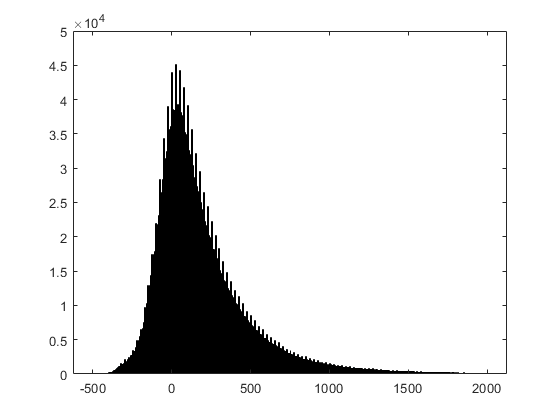

%Analysis Section
%Histogram for the difference between the time Google Calculated and the actual time.

    travelTimeDifference = zOut_SingleTrips.Travel_Time_Seconds - zOut_SingleTrips.bicy_google_time;
    h = histogram(travelTimeDifference,400,'BinLimits',[-500,2000]);

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


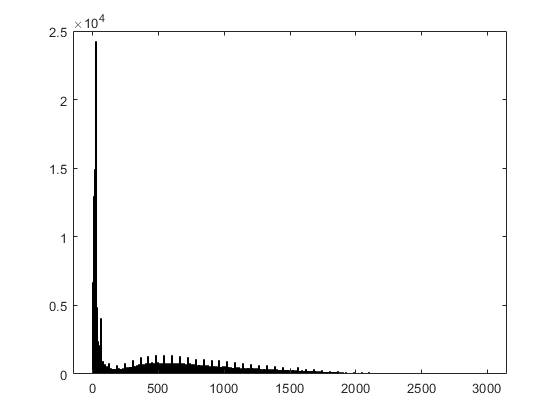

    h_mean = mean(travelTimeDifference);
    h_std = std(travelTimeDifference);

%Histogram for the duration of the round trips.

    h1 = histogram(zOut_RoundTrips.Travel_Time_Seconds,400,'BinLimits',[0,3000]);

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


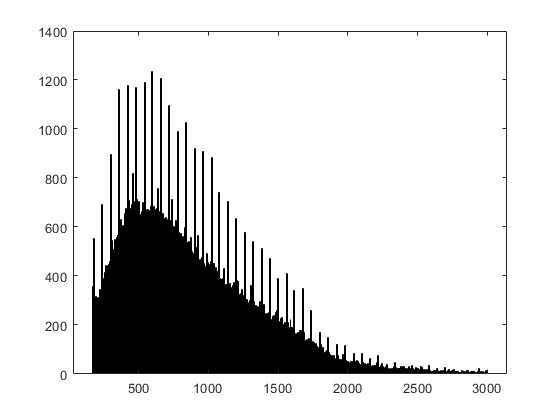


%Filter Values less than 170, it is assumed to be regrets of Bike usage. (Value Choosen from looking at previous figure)
    h2 = histogram(zOut_RoundTrips.Travel_Time_Seconds,400,'BinLimits',[170,3000]);

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


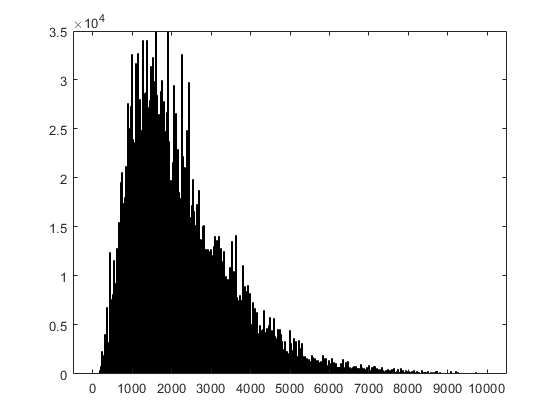


%Histogram of the estimated travel distances per user on a single trip
    h3 = histogram(zOut_SingleTrips.bicy_google_distance,400,'BinLimits',[0,10000]);

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


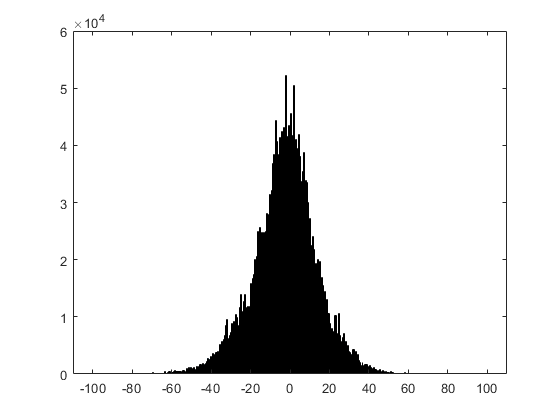

    h3_mean = mean(zOut_SingleTrips.bicy_google_distance);
    h3_std = std(zOut_SingleTrips.bicy_google_distance);

%Histogram of the difference on altitude between the origin and the destination.
    altitudeDifference = zOut_SingleTrips.altitude_dest - zOut_SingleTrips.altitude_origin;
    h4 = histogram(altitudeDifference,400,'BinLimits',[-100,100]);

    h4_mean = mean(altitudeDifference);
    h4_std = std(altitudeDifference);

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 1 sec


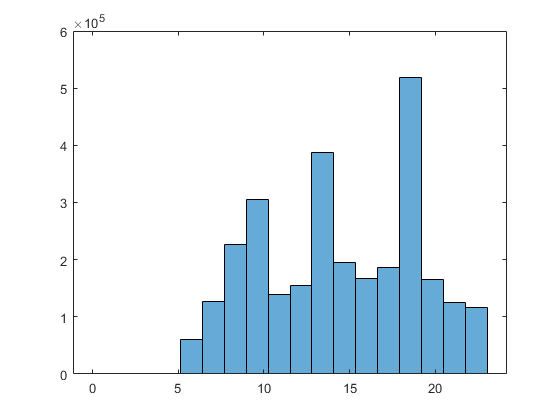

%Histogram of the distribution of trips along a single day
    [hours,~,~] = hms(zOut_SingleTrips.Inicio_del_viaje);
    h5 = histogram(hours,18);

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


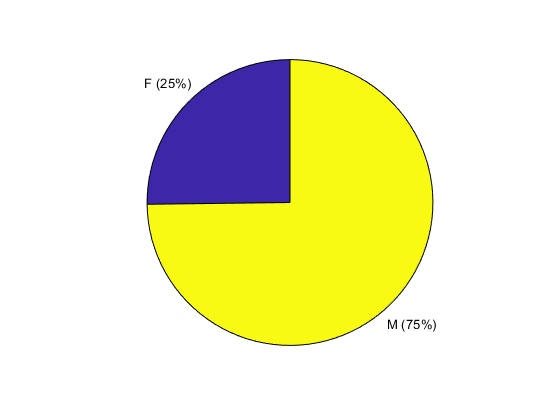


%Pie chart of users.
    p = pie(zOut_SingleTrips.Genero);

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


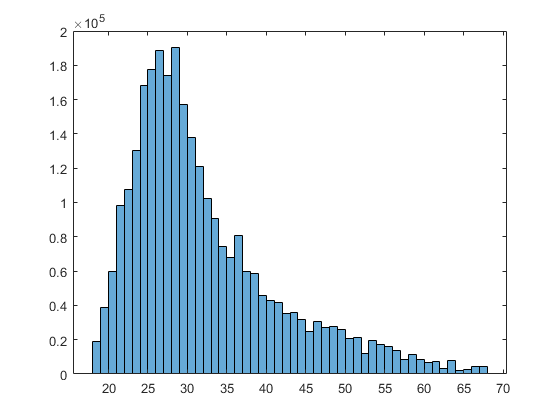


%Histogram Ages of Users
    AgeOfUsers = (2018 - zOut_SingleTrips.Ao_de_nacimiento);
    h6 = histogram(AgeOfUsers,50,'BinLimits',[18,68]);

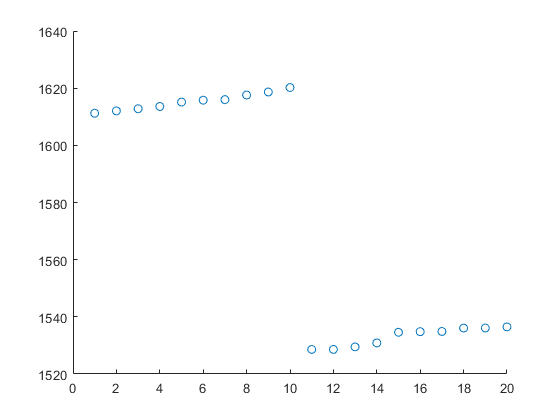

    h6_mean = nanmean(AgeOfUsers);
    h6_std = nanstd(AgeOfUsers);
    
%Plot of highest ten and lowest ten altitudes station-wise

    max10_Elev_Station = maxk(StationsDatabase(:,4),10);
    min10_Elev_station = mink(StationsDatabase(:,4),10);
    
    scatter(1:20,[fliplr(max10_Elev_Station'),min10_Elev_station']);

%Group Stats
%Plot of travelled distance per user age
    Travel_vs_UserAge_means = gather(grpstats(zOut_SingleTrips, 'Ao_de_nacimiento'));

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 10 sec


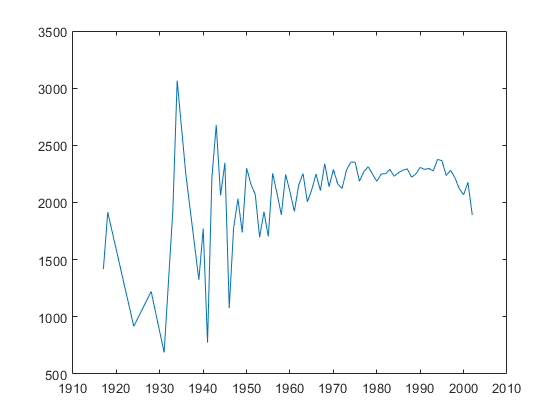

    plot(Travel_vs_UserAge_means.Ao_de_nacimiento, Travel_vs_UserAge_means.mean_bicy_google_distance);


%Analysis per user
    PerUserAnalysis = grpstats(zOut_SingleTrips,'Usuario_Id');
    ActiveUsersOnDatabase = gather(size(PerUserAnalysis));

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 28 sec


    ActiveUsersOnDatabase = ActiveUsersOnDatabase(1);
    [~,Top30ActiveUsers_I] = maxk(PerUserAnalysis.GroupCount,30);
    

    %Lets get UserId of the most active users.
    Top30ActiveUsers_I = gather(Top30ActiveUsers_I);

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


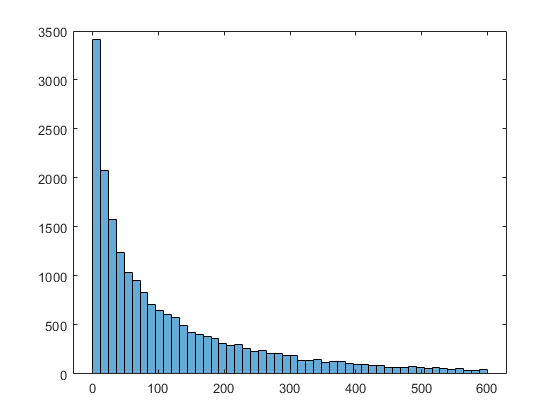

    Top30ActiveUsers = PerUserAnalysis(Top30ActiveUsers_I,'Usuario_Id');
    
    
    h7 = histogram(PerUserAnalysis.GroupCount,50,'BinLimits',[0,600]); %Histogram of uses per analyzed database data.

    h7_mean = nanmean(PerUserAnalysis.GroupCount);
    h7_std = nanstd(PerUserAnalysis.GroupCount);

%Let's Analyze the users trip data to identify
%First let's organize the data by user and trip date and time

MySortData = sortrows(zOut_SingleTrips,'Inicio_del_viaje');
MySortData = sortrows(MySortData,'Usuario_Id');

%Let's continue analyzing trip data, sortrows took too much time.

Helper_InitialTime = [table2array(MySortData(:,6)); datetime + 365 * 10];
Helper_InitialTime = Helper_InitialTime(2:end);

TripCalculation = Helper_InitialTime - table2array(MySortData(:,7));
ConsecutiveTripsIdentified = (TripCalculation < duration(0,5,0)) & (TripCalculation > duration(0,0,0)) ;

HelperTrips = find(ConsecutiveTripsIdentified);
HelperTrips = HelperTrips + 1;


RAM_ConsecutiveTripsIdentified = gather(ConsecutiveTripsIdentified);
RAM_ConsecutiveTripsIdentified(gather(HelperTrips)) = true;

ConsecutiveTripsIdentified = tall(RAM_ConsecutiveTripsIdentified);

AllConsecutiveTrips = gather(MySortData(ConsecutiveTripsIdentified,:));

Evaluating tall expression using the Parallel Pool 'local':
Evaluation completed in 0 sec


%AllConsecutiveTrips = sortrows(AllConsecutiveTrips,'Usuario_Id');
